# サッカー　Eloレーティングを求めて予測に活用する

clear;clc;close all;

データの読み込みと前処理

load predictionModel.mat mdl
tbl=readtable('../../data/archive/results.csv','encoding','UTF-8');
teamNames=unique([tbl.home_team;tbl.away_team]);
tbl.home_team=categorical(tbl.home_team,teamNames);
tbl.away_team=categorical(tbl.away_team,teamNames);
teamNames=categorical(teamNames);
tbl.tournament=categorical(tbl.tournament);
tbl.neutral=str2mat(tbl.neutral)

tbl = 47598×9 table
       date       home_team    away_team    home_score    away_score    tournament       city          country       neutral
    __________    _________    _________    __________    __________    __________    ___________    ____________    _______

    1872/11/30    Scotland     England          0             0          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1873/03/08    England      Scotland         4             2          Friendly     {'London' }    {'England' }     FALSE 
    1874/03/07    Scotland     England          2             1          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1875/03/06    England      Scotland         2             2          Friendly     {'London' }    {'England' }     FALSE 
    1876/03/04    Scotland     England          3             0          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1876/03/25    Scotland     Wales            4             0          Friendly     {'Glasgow'}    {'S

summary(tbl)

Variables:

    date: 47598×1 datetime

        Values:

            Min       1872/11/30
            Median    1999/08/18
            Max       2024/09/10

    home_team: 47598×1 categorical

        Values:

            Abkhazia                               22   
            Afghanistan                            46   
            Albania                               201   
            Alderney                               48   
            Algeria                               335   
            Ambazonia                               0   
            American Samoa                         24   
            Andalusia                              12   
            Andorra                               107   
            Angola                                194   
            Anguilla                               28   
            Antigua and Barbuda                   125   
            Arameans Suryoye                        3   
            Arg

予測対象大会の設定，訓練データと検証データの分割

ind = tbl.tournament=='FIFA World Cup' ...
    & tbl.date>=datetime(2022,11,20) ...
    & tbl.date<=datetime(2022,12,18);

tbl_test=tbl(ind,:)

tbl_test = 64×9 table
       date         home_team       away_team      home_score    away_score      tournament          city          country     neutral
    __________    _____________    ____________    __________    __________    ______________    _____________    _________    _______

    2022/11/20    Qatar            Ecuador             0             2         FIFA World Cup    {'Al Khor'  }    {'Qatar'}     FALSE 
    2022/11/21    Senegal          Netherlands         0             2         FIFA World Cup    {'Doha'     }    {'Qatar'}     TRUE  
    2022/11/21    England          Iran                6             2         FIFA World Cup    {'Al Rayyan'}    {'Qatar'}     TRUE  
    2022/11/21    United States    Wales               1             1         FIFA World Cup    {'Al Rayyan'}    {'Qatar'}     TRUE  
    2022/11/22    Argentina        Saudi Arabia        1             2         FIFA World Cup    {'Lusail'   }    {'Qatar'}     TRUE  
    2022/11/22    Mexico        

teamNames_test=unique([tbl_test.home_team;tbl_test.away_team]);
tbl_train=tbl(tbl.date<datetime(2022,11,20),:);

Eloレーティング算出(ホームアドバンテージを考慮しない)

r=zeros(size(teamNames));
K=log(10)/400*32

K = 0.1842

for n1=1:size(tbl_train,1)
    taName=tbl_train.home_team(n1);
    tbName=tbl_train.away_team(n1);
    taNum=find(teamNames==taName);
    tbNum=find(teamNames==tbName);

    taGoals=tbl.home_score(n1);
    tbGoals=tbl.away_score(n1);

    % 結果
    if taGoals>tbGoals
        s=1;
    elseif taGoals==tbGoals
        s=0.5;
    else
        s=0;
    end

    % 予測勝率
    taRating=r(taNum);
    tbRating=r(tbNum);

    p=1./(1+exp(tbRating-taRating));
    r(taNum)=r(taNum)+K*(s-p);
    r(tbNum)=r(tbNum)-K*(s-p);

end

予測対象の大会に出場するチームの情報を示すtableをつくる

tbl_team=table();
tbl_team=addvars(tbl_team, ...
    teamNames,'NewVariableNames','Team');
tbl_team=addvars(tbl_team, ...
    r,'NewVariableNames','EloRating');
tbl_team=addvars(tbl_team, ...
    countcats([tbl.home_team;tbl.away_team]), ...
    'NewVariableNames','Matches');

tbl_team=sortrows(tbl_team,"EloRating","descend");
ind=ismember(tbl_team.Team, teamNames_test);
tbl_team=tbl_team(ind,:)

tbl_team = 32×3 table
       Team        EloRating    Matches
    ___________    _________    _______

    Brazil          3.3508       1042  
    Argentina       3.1162       1049  
    Spain           2.7923        760  
    Netherlands     2.7445        853  
    France          2.6586        910  
    Belgium         2.5464        829  
    Portugal        2.5292        677  
    England         2.5126       1072  
    Germany         2.4587       1010  
    Denmark         2.3561        852  
    Croatia         2.2148        378  
    Uruguay         2.2111        950  
    Switzerland     2.0527        864  
    South Korea     1.9873        992  
    Serbia          1.9697        328  
    Iran            1.9541        596  


図示

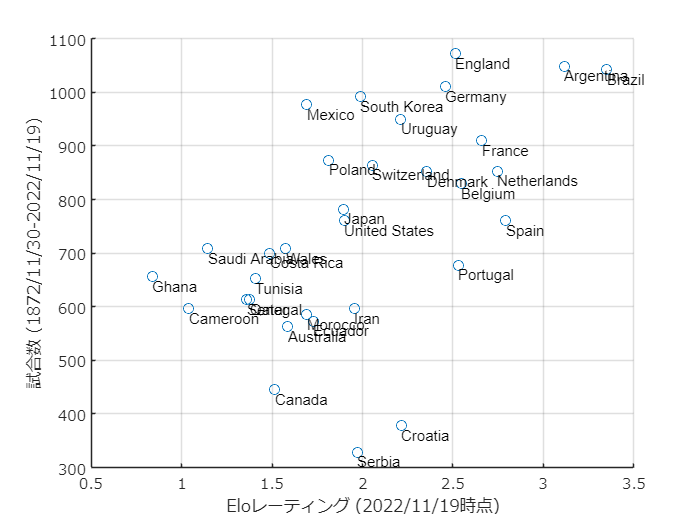

figure;
scatter(tbl_team.EloRating, tbl_team.Matches);hold on;grid on;
set(gca,'fontname','メイリオ');
xlabel(['Eloレーティング (' datestr(max(tbl_train.date),'yyyy/mm/dd') '時点)']);
ylabel(['試合数 (' datestr(min(tbl_train.date),'yyyy/mm/dd') '-' datestr(max(tbl_train.date),'yyyy/mm/dd') ')']);
for n1=1:size(tbl_team,1)
    text(tbl_team.EloRating(n1), tbl_team.Matches(n1),[' ' tbl_team.Team(n1)], ...
        'fontname','Arial')
end
exportgraphics(gcf,'fig_internationalFootball_EloRaing_WC2022.pdf');

直接対決での予測勝点

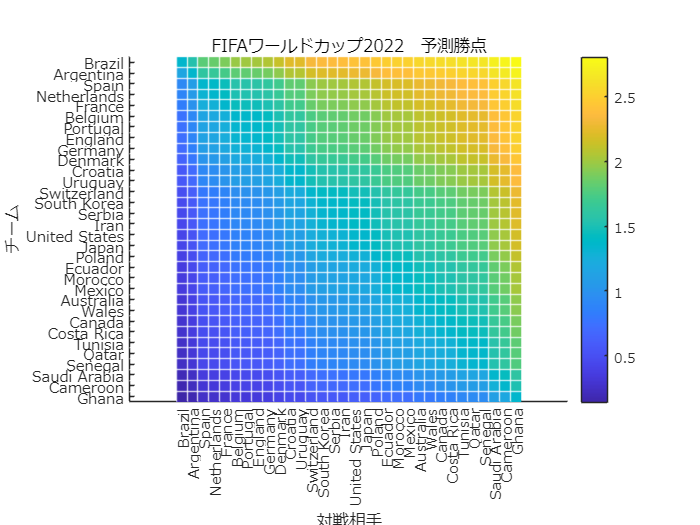

plotData=zeros(size(tbl_team,1));
for n1=1:size(tbl_team,1)
    for n2=1:size(tbl_team,1)
        taRating=tbl_team.EloRating(n1);
        tbRating=tbl_team.EloRating(n2);
        rateDiff=taRating-tbRating;
        pLose=glmval(mdl(1,:)',rateDiff,'logit');
        pDraw=glmval(mdl(2,:)',rateDiff,'logit')-pLose;
        pWin=1-pDraw-pLose;

        plotData(n1,n2)=3*pWin+pDraw;
    end
end
figure;axis equal;set(gca,'fontname','メイリオ');hold on;
xticks(1:size(tbl_team,1));xticklabels(tbl_team.Team);
yticks(1:size(tbl_team,1));yticklabels(tbl_team.Team);
set(gca,'ydir','reverse');colorbar;
ylabel('チーム');xlabel('対戦相手');
for n1=1:size(tbl_team,1)
    xline(n1-0.5,'w');yline(n1-0.5,'w');
end
imagesc(plotData);
title('FIFAワールドカップ2022　予測勝点');
exportgraphics(gcf,'fig_WC2022_Prediction_expectedPoints.pdf');

予測勝率の算出

rateDiff=[];pWin=[];
for n1=1:size(tbl_test,1)
    taName=tbl_test.home_team(n1);
    tbName=tbl_test.away_team(n1);
    taNum=find(teamNames_test==taName);
    tbNum=find(teamNames_test==tbName);

    taRating=tbl_team.EloRating(taNum);
    tbRating=tbl_team.EloRating(tbNum);
    rateDiff=[rateDiff;taRating-tbRating];
end

tbl_test=addvars(tbl_test, 1-glmval(mdl(2,:)', rateDiff,'logit'), ...
    'NewVariableNames','pWin');
tbl_test=addvars(tbl_test, ...
    glmval(mdl(2,:)', rateDiff,'logit')-glmval(mdl(1,:)',rateDiff,'logit'), ...
    'NewVariableNames','pDraw');
tbl_test=addvars(tbl_test, glmval(mdl(1,:)', rateDiff,'logit'), ...
    'NewVariableNames','pLose');

xPA=tbl_test.pWin*3+tbl_test.pDraw;
xPB=tbl_test.pLose*3+tbl_test.pDraw;
tbl_test=addvars(tbl_test, xPA);
tbl_test=addvars(tbl_test, xPB);
pWin=1./(1+exp(-rateDiff));
goalDiff=[tbl_test.home_score-tbl_test.away_score];

得失点差との関係を図示

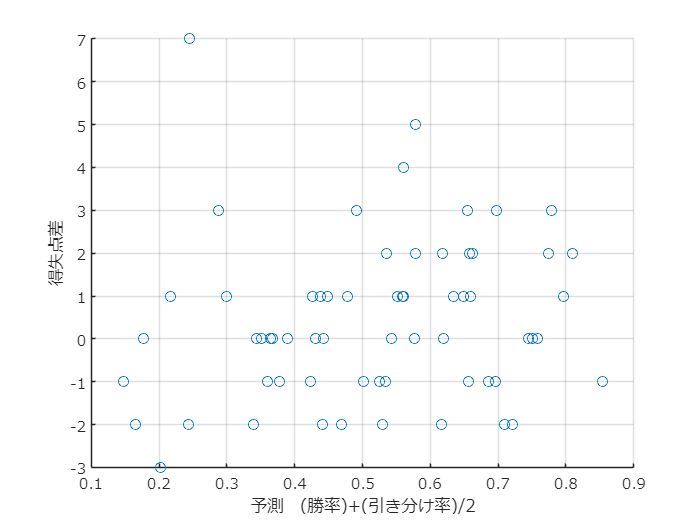

figure;hold on;grid on;set(gca,'fontname','メイリオ');
scatter(pWin, goalDiff);
xlabel('予測　(勝率)+(引き分け率)/2');
ylabel('得失点差');

pWin=[pWin;1-pWin];
goalDiff=[goalDiff;-goalDiff];

ind_win=goalDiff>0;
ind_draw=goalDiff==0;
ind_lose=goalDiff<0;

ind_s=pWin>0.5;

pWin=pWin(ind_s);
ind_win=ind_win(ind_s);
ind_draw=ind_draw(ind_s);
ind_lose=ind_lose(ind_s);
goalDiff=goalDiff(ind_s);

較正値の算出

[予測勝率の合計　実際の(勝利数)+(引き分け数)/2]

[sum(pWin) (sum(ind_win)+0.5*sum(ind_draw))]

ans =    41.7235   36.5000


calibVal=sum(pWin)/(sum(ind_win)+0.5*sum(ind_draw))

calibVal = 1.1431

bins=0.5:0.05:1;
hCounts=[histcounts(pWin(ind_lose),bins);
    histcounts(pWin(ind_draw),bins);
    histcounts(pWin(ind_win),bins);
    ]

hCounts =      6     3     1     3     4     2     0     1     0     0
     1     3     5     1     1     3     1     0     0     0
     2     8     5     6     0     5     2     1     0     0


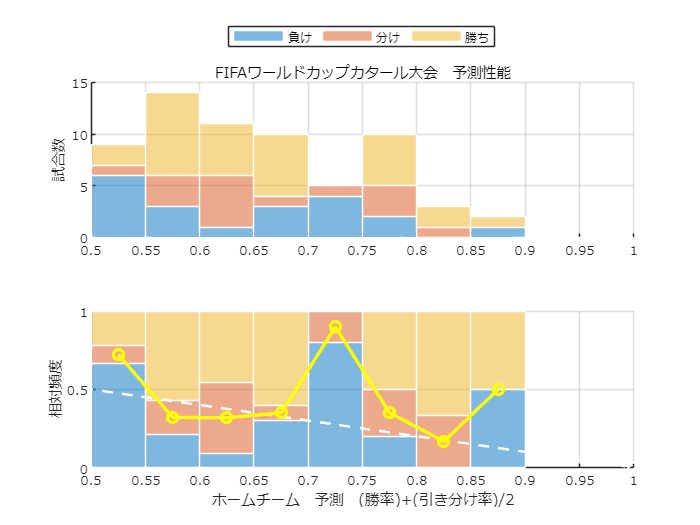

aRatio=(hCounts(1,:)+1/2*hCounts(2,:))./sum(hCounts);

figure
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');
title('FIFAワールドカップカタール大会　予測性能')

bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('試合数');
xlim([0.5 1]);

nexttile;
set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts,1),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
plot([0 1],[1 0],'ow--','LineWidth',1.5);
xlim([0.5 1]);
plot(movmean(bins,2,'Endpoints','discard'),aRatio,'yo-','LineWidth',2)
xlabel('ホームチーム　予測　(勝率)+(引き分け率)/2');
ylabel('相対頻度');
exportgraphics(gcf,['fig_WC2022_PredictionPerformance.pdf']);

チームごとの予測勝率と実勝敗

xP=zeros(size(tbl_team,1),1);
aP=zeros(size(tbl_team,1),1);
for n1=1:48
    taNum=find(tbl_team.Team==tbl_test.home_team(n1));
    tbNum=find(tbl_team.Team==tbl_test.away_team(n1));
    xP(taNum)=xP(taNum)+tbl_test.xPA(n1);
    xP(tbNum)=xP(tbNum)+tbl_test.xPB(n1);

    if tbl_test.home_score(n1)>tbl_test.away_score(n1)
        aP(taNum)=aP(taNum)+3;
    elseif tbl_test.home_score(n1)==tbl_test.away_score(n1)
        aP(taNum)=aP(taNum)+1;
        aP(tbNum)=aP(tbNum)+1;

    else
        aP(tbNum)=aP(tbNum)+3;
    end
end

tbl_team=addvars(tbl_team, xP, aP);

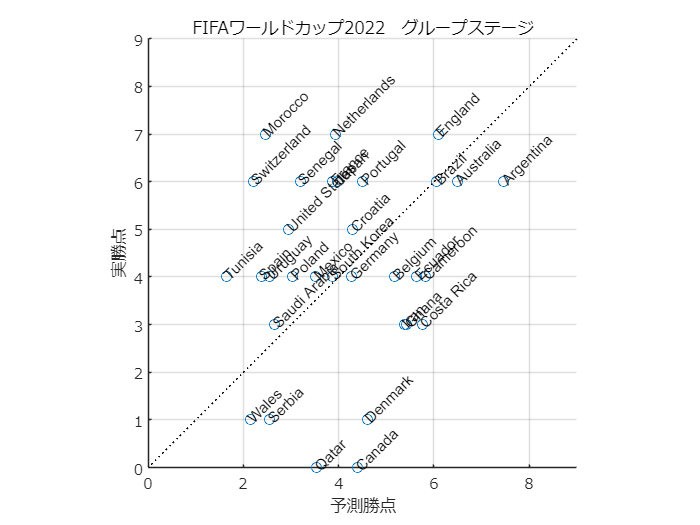

figure;hold on;
scatter(tbl_team.xP, tbl_team.aP,'o');
axis equal;grid on;
set(gca,'fontname','メイリオ');
axis([0 9 0 9]);plot([0 9],[0 9],'k:');
text(tbl_team.xP, tbl_team.aP, tbl_team.Team, ...
    'fontname','Arial','rotation',45);
xlabel('予測勝点');ylabel('実勝点');title('FIFAワールドカップ2022　グループステージ');
exportgraphics(gcf,['fig_WC2022_PredictionByTeam.pdf']);